ECSE 403 - Lab 5

%Q1
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.




G = 1/(0.4549*s^2+11.56*s)


G =
 
           1
  --------------------
  0.4549 s^2 + 11.56 s
 
Continuous-time transfer function.



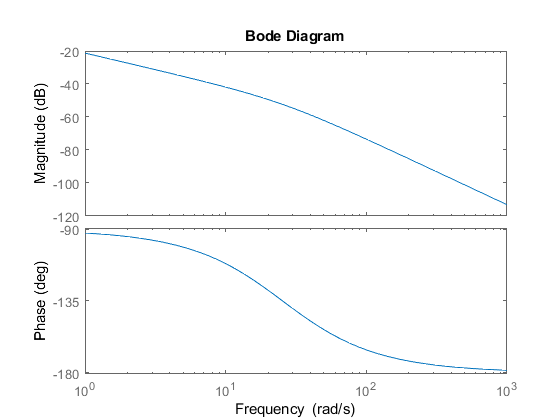


bode(G)

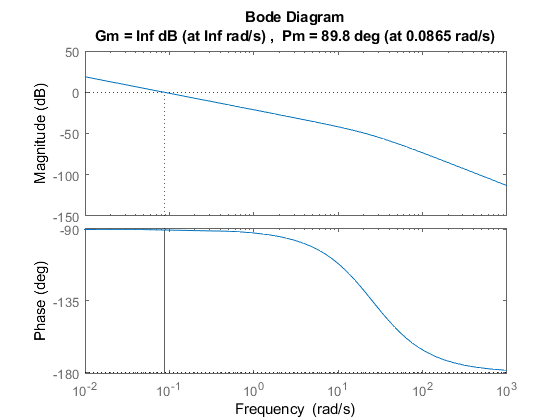

margin(G)


%Q2
Kp=60;
G2=Kp*G


G2 =
 
           60
  --------------------
  0.4549 s^2 + 11.56 s
 
Continuous-time transfer function.



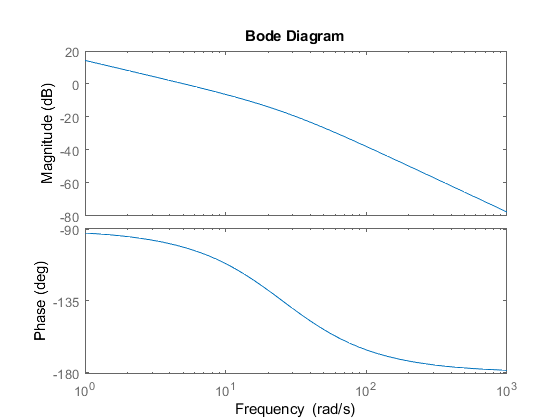


bode(G2)

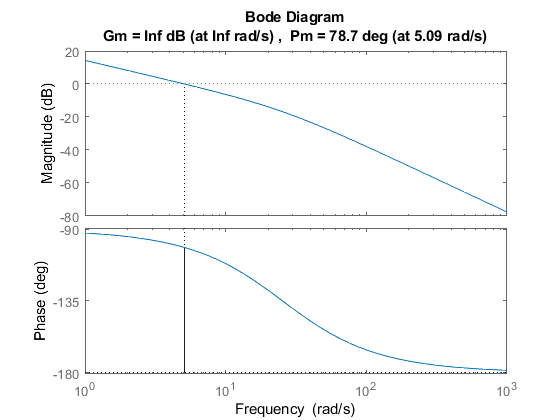

margin(G2)


phi=16;
alpha= (1-sin(phi))/(1+sin(phi))

alpha = 1.8086


-20*log(1*sqrt(alpha))

ans = -5.9256


wm=9.62;
T = 1/(wm*sqrt(alpha))

T = 0.0773


Clead=1*((alpha*T*s+1)/(T*s+1))


Clead =
 
  0.1398 s + 1
  ------------
  0.0773 s + 1
 
Continuous-time transfer function.




G3=Clead*G2


G3 =
 
            8.388 s + 60
  ---------------------------------
  0.03516 s^3 + 1.348 s^2 + 11.56 s
 
Continuous-time transfer function.



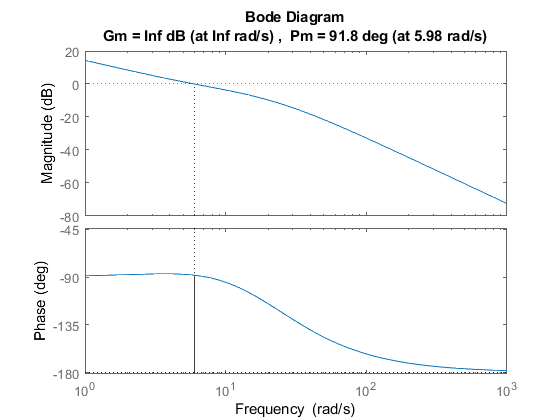

margin(G3)

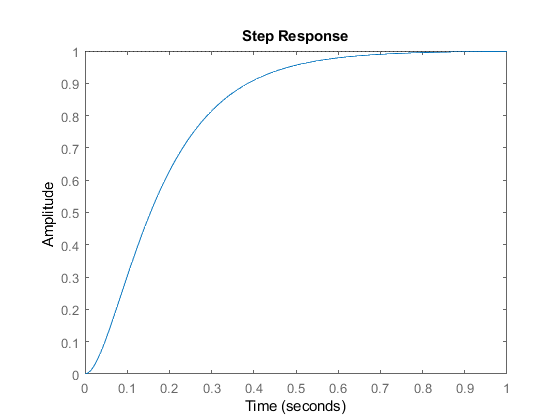

%Q3
step(feedback(G2,1))

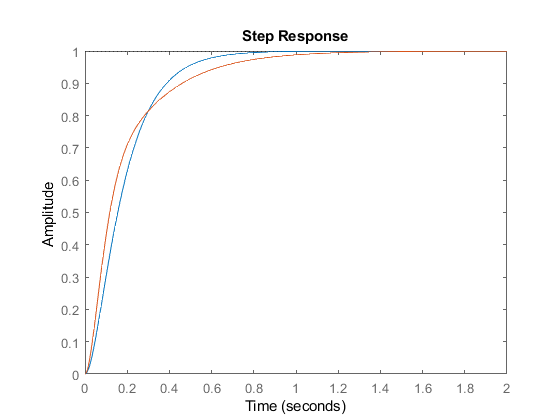

step(feedback(G2,1))
hold on
step(feedback(G3,1))
hold off

%Q6
C_lag = 7.2*(0.59*s+1)/(2.52*0.59*s+1)


C_lag =
 
  4.248 s + 7.2
  -------------
   1.487 s + 1
 
Continuous-time transfer function.



G4 = C_lag * G3


G4 =
 
           35.63 s^2 + 315.3 s + 432
  --------------------------------------------
  0.05228 s^4 + 2.04 s^3 + 18.54 s^2 + 11.56 s
 
Continuous-time transfer function.



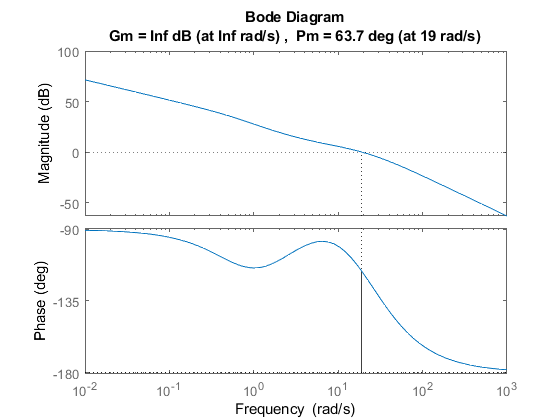

margin(G4)

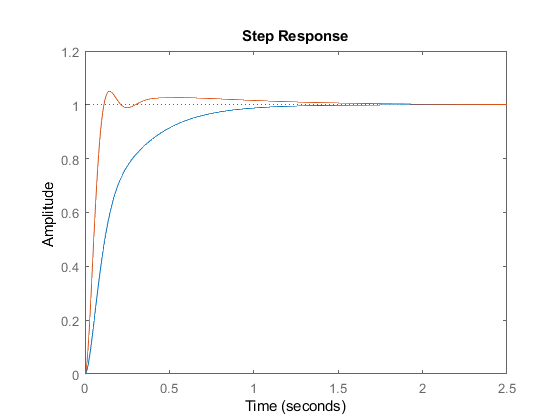


%Q7

step(feedback(G3,1))
hold on
step(feedback(G4,1))
hold off

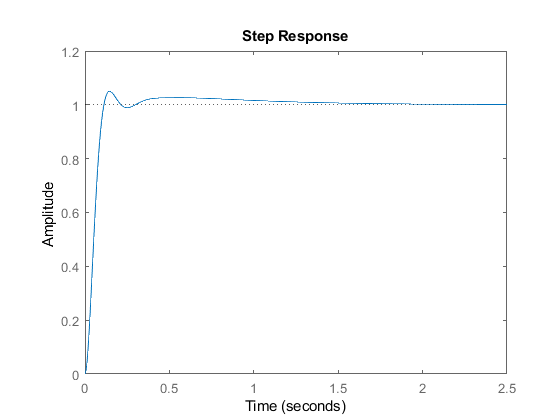


step(feedback(G4,1))